## MA 402 Project 2

### Monday May 2, 2022

### Andrea Stancescu, Jenna Varnell, Omry Bewster

% Andrea Stancescu, Jenna Varnell, Omry Brewster
% MA 402 Project 2 
% 5-2-2022
% MATLAB .mlx file with integrated text and code

### 1. Introduction

*insert a description here of correlation, clustering, and least squares prediction and why is it useful for analyzing data sets**

make sure to add figure labels (subtitles) to each plot and descriptions to each plot (title and axes names)

### 2. Preliminaries - Data Exploration 

We start with loading the joke data which contains 4 items:

1) JTrain, a matrix of size 63 × 42 containing ratings of 42 jokes from 63 students over past semesters. Jokes were rated on a scale of 0 (not funny) to 10 (hilarious). Not all entries of JTrain are integers since the professor took the liberty of filling in some missing entries.

2) jokes, a cell array of length 42 containing a one-word descriptor for each joke.

3) jokeTexts, a cell array of length 42 containing the full text of each joke.

4) JTest, a matrix of size 36×20 containing ratings from this semester’s students of the first 20 jokes in the survey. Responses for the remaining 22 jokes are withheld by the professor.

(a) First we will find the jokes with the highest and lowest ratings over JTrain. We do this by finding the mean of each column in JTrain and finding the maximum and minimum of this resulting vector of averages.  

% a) Find the jokes with the highest and lowest ratings over JTrain.
% aka find the mean of each column (joke) and find smallest and largest average / mean 
 avg = mean(JTrain,1);
% return 42 length vector with the mean score of each columns / joke 
[score_f, funniest] = max(avg);
fprintf("The funniest joke is the %s joke which says ''%s'' \n", char(jokes(funniest)), char(jokeTexts(funniest)))

The funniest joke is the Hotel joke which says ''An engineer, a physicist and a mathematician are sleeping in a room. There is a fire in the room. The engineer wakes up, sees the fire, picks up the bucket of water and douses the fire and goes back to sleep.   Again there is fire in the room. This time, the physicist wakes up, notices the bucket, fills it with water, calculates the optimal trajectory and douses the fire in minimum amount of water and goes back to sleep.  Again there is fire. This time the mathematician wakes up.  He looks at the fire, looks at the bucket and the water and exclaims, "A solution exists" and goes back to sleep.'' 


[score_l, nonfunny] = min(avg);
fprintf("The least funny joke is the %s joke which says ''%s'' \n", char(jokes(nonfunny)), char(jokeTexts(nonfunny)))

The least funny joke is the Rabbit joke which says ''Two cows are in a field. Suddenly, from behind a bush, a rabbit leaps out and runs away. One cow looks around a bit, eats some grass, and then wanders off. '' 


(b) Next we will find the person that gave the highest average rating on the jokes. We do this by finding the row-wise mean of JTrain. We are also finding the jokes that this specific person disliked the most. We do this by finding the minimum(s) in the row that corresponds with the student we just found. 

person = mean(JTrain, 2);
% return a 63 x 1 length vector with mean score of each individual
[score_p, highestperson] = max(person);
fprintf("The individual who gave the highest average joke rating is the %d person with an avergae joke rating of %f \n", highestperson , score_p)

The individual who gave the highest average joke rating is the 11 person with an avergae joke rating of 8.000000 


% find which joke the 11th person liked the least
person_data = JTrain(11,:);
overallworst_score = min(person_data);
[worst_scores, worst_jokes] = find(person_data == overallworst_score);
fprintf("The individual who gave the highest average joke rating gave two low ratings of %d. \nThe jokes that recieved these ratings were: \nthe %s joke which says ''%s'' \nand \nthe %s joke which says ''%s'' \n ", overallworst_score, char(jokes(worst_jokes(1))), char(jokeTexts(worst_jokes(1))), char(jokes(worst_jokes(2))), char(jokeTexts(worst_jokes(2))))  

The individual who gave the highest average joke rating gave two low ratings of 6. 
The jokes that recieved these ratings were: 
the Holmes joke which says ''Sherlock Holmes and Dr. Watson go on a camping trip, set up their tent, and fall asleep. Some hours later, Holmes wakes his faithful friend. "Watson, look up at the sky and tell me what you see." Watson replies, "I see millions of stars." "What does that tell you?" Watson ponders for a minute. "Astronomically speaking, it tells me that there are millions of galaxies and potentially billions of planets. Astrologically, it tells me that Saturn is in Leo. Timewise, it appears to be approximately a quarter past three. Meteorologically, it seems we will have a beautiful day tomorrow. What does it tell you?" Holmes is silent for a moment, then speaks. "Watson, you idiot, someone has stolen our tent."'' 
and 
the Ball joke which says ''A mathematician, physicist, and engineer are asked to measure the volume of a red rubber ball. The math

(c) We will use the function pcolor() in matlab and the colorbar option to get a quick view of the entire data set. The pcolor() function in MATLAB creates a pseudocolor plot using the values in matrix C. A pseudocolor plot displays matrix data as an array of colored cells (known as faces). MATLAB creates this plot as a flat surface in the x-y plane as seen below. 

Find at least one person who did not appear to take their joke-rating duties seriously, and make a histogram of their ratings.

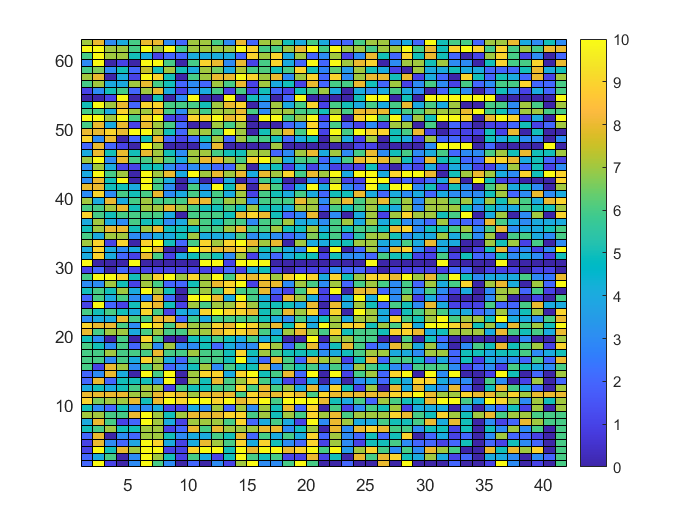


figure(1)
pcolor(JTrain)
colorbar

The color bar shows that deep blue corresponds to a rating of 0 (not at all funny) whereas bright yellow corresponds to a rating of 10 (very funny)

By clicking on the colored cells, it can be seen that individual 30 did not seem to take it seriously as they rated nearly all of the jokes with very low scores (which can be seen by a row shaded nearly entirely dark blue). When examining the scores that individual 30 gave it can be seen that they only rated jokes 10, 0, or 1 showing that they did not take the time to read and consider each joke. 

The pcolor plot below shows that individual 30 rated jokes with only extreme answers (0 or 10) suggesting lack of consideration.

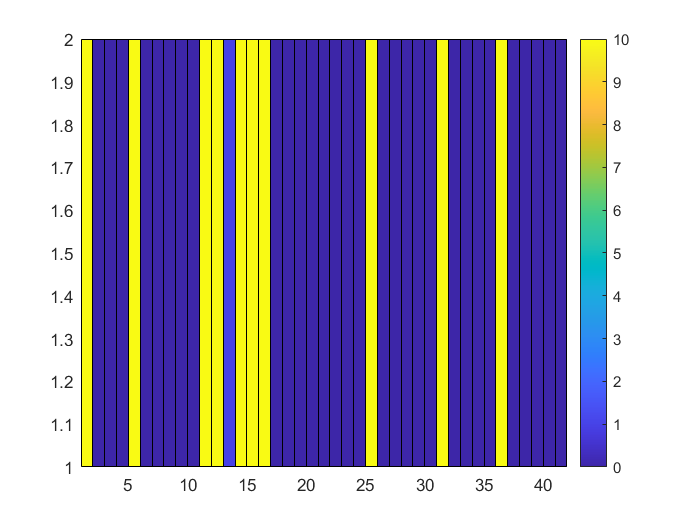

figure(2)
individ30 = JTrain(30,:);
emptyrow = zeros(1,42);
pcolor([individ30 ; emptyrow])
colorbar

Individual 11 did not seem to take it seriously either as they rated nearly all of the jokes with very high scores (as can be seen by a row shaded nearly entirely yellow). When examining the scores that inidivudal 11 gave it can be seen that they only rated jokes 7, 8, 9, 10 which suggests that they might have just given every joke a high score regardless of its true comedy value.

The pcolor plot below shows nearly all questions are yellow or light green suggesting a lack of thoughtfulness. 

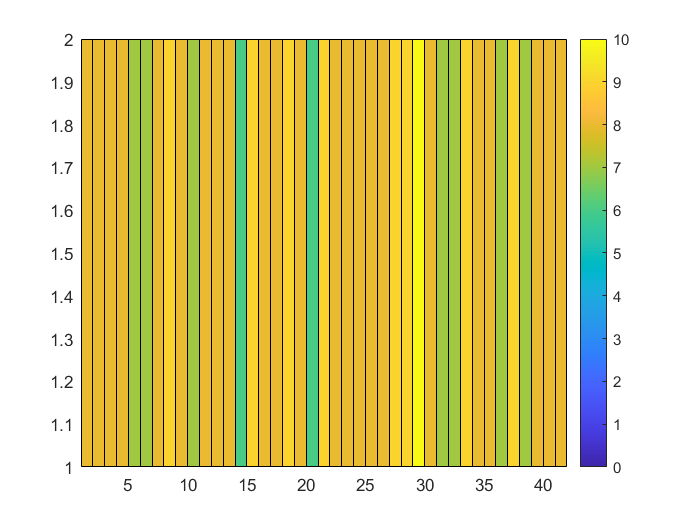

figure(3)
individ11 = JTrain(11, :);
emptyrow = zeros(1, 42);
pcolor([individ11 ; emptyrow])
colorbar

d) Below we will find two jokes whose ratings were strongly correlated. We will do this by first finding rho, a 42 x 42 matrix of correlation coefficients found via the corrcoef() function in MATLAB. Here the main diagonal has every entry equal to 1 (since $\rho \left(X,X\right)=\frac{\mathrm{COV}\left(X,X\right)}{V\left(X\right)}=1$ ). Moreover, correlations are always bounded between 0 and 1. Since we are looking to find the highest correlations between jokes, we will set the main diagonal to be 0 in order to take those values out of consideration (since we will not be examining the correlation of a joke with itself).

rho = corrcoef(JTrain);
% maximum possible correlation is 1
for i = 1:42
    rho(i, i) = 0;
end 
colmax = max(rho);
largesttwo = maxk(colmax, 4);

We will then find which two pairs of jokes have the largest correlation and report them below.

The spherical and ball joke seem somewhat related since both require some degree of thought and sophistication. Moreover, both jokes are slightly longer (in comparison to the other 40 jokes) and seem to require more thought.

[r1,c1] = find(rho == largesttwo(1));
% joke 20 and 22 have the highest correlation 
fprintf("The 2 jokes with the highest correlation are jokes %d and %d with a correlation of %f \nThis is the %s joke which says ''%s'' \nand the %s joke which says ''%s''. \n ", r1(1), r1(2), rho(r1(1),r1(2)), char(jokes(r1(1))), char(jokeTexts(r1(1))), char(jokes(r1(2))), char(jokeTexts(r1(2))) )

The 2 jokes with the highest correlation are jokes 22 and 20 with a correlation of 0.719332 
This is the Spherical joke which says ''Milk production at a dairy farm was low, so the farmer wrote to the local university asking for help. A physicist comes to the farm for an intensive on-site investigation, and returns to the univeristy to evaluate the data. The physicist soon returns to the farm, saying to the farmer "I have the solution, but it works only in the case of spherical cows in a vacuum".'' 
and the Ball joke which says ''A mathematician, physicist, and engineer are asked to measure the volume of a red rubber ball. The mathematician measures the circumference with a string, then computes the volume. The physicist puts the ball in a beaker of water and measures the displacement. The engineer weighs the ball, then looks up the conversion formula in a Red Rubber Ball table. ''. 
 

The attorneys and positive joke do not seem to be very related however, they both incorporate some degree of thought and prior knowledge. 

Overall, it can be seen why these two pairs of jokes have larger correlation.

fprintf("\n")
[r2, c2] = find(rho == largesttwo(3));
% joke 11 and 12 have the second highest correlation 
fprintf("The 2 jokes with the second highest correlation are jokes %d and %d with a correlation of %f \nThis is the %s joke which says ''%s'' \nand the %s joke which says ''%s''. \n ", r2(1), r2(2), rho(r2(1),r2(2)), char(jokes(r2(1))), char(jokeTexts(r2(1))), char(jokes(r2(2))), char(jokeTexts(r2(2))) )

The 2 jokes with the second highest correlation are jokes 12 and 11 with a correlation of 0.646219 
This is the Attorneys joke which says ''Two attorneys went into a diner and ordered two drinks.  Then they produced  sandwiches from their briefcases and started to eat.  The owner became quite concerned and marched over and told them, "You can't eat your own sandwiches in here!"  The attorneys looked at each other, shrugged their shoulders and then exchanged sandwiches.'' 
and the Positive joke which says ''Two atoms are walking down the street when one  atom says to the other  "Oh, my! I've lost an electron!"  The second atom says"Are you sure"  The first replies "I'm positive!"''. 
 

e) Below we will now find two people whose joke ratings were strongly correlated. We will then make a scatterplot of the ratings of one person versus the ratings of the other.

In order to do this we must find the correlation coefficient matrix of the transpose of JTrain. Here ${\mathrm{JTrain}}^T$ results in a 42 x 63 matrix where each individual's responses are treated as a random vector.

Then using the maxk() function, we wil find the largest two distinct correlations in the correlation coefficient matrix.

rho2 = corrcoef(JTrain');
for i = 1:63
    rho2(i, i) = 0;
end 
colmax = max(rho2);
largesttwo = maxk(colmax, 4);



[r1,c1] = find(rho2 == largesttwo(1));
% person 5 and 32 have the highest correlation 
fprintf("The 2 individuals with the highest correlated responses are person %d and %d with a correlation of %f  \n ", r1(1), r1(2), rho2(r1(1),r1(2)) )

The 2 individuals with the highest correlated responses are person 32 and 5 with a correlation of 0.721350  
 

fprintf("\n")
[r2, c2] = find(rho2 == largesttwo(3));
% person 50 and 53 have the second highest correlation 
fprintf("The 2 individuals with the second highest correlated responses are person %d and %d with a correlation of %f  \n ", r2(1), r2(2), rho2(r2(1),r2(2)) )

The 2 individuals with the second highest correlated responses are person 53 and 50 with a correlation of 0.698254  
 

The plots below show a visual graphic of the correlation between the two pairs of individuals' responses. It can be seen that both have a moderately strong positive trend which is supported by the high correlation value.

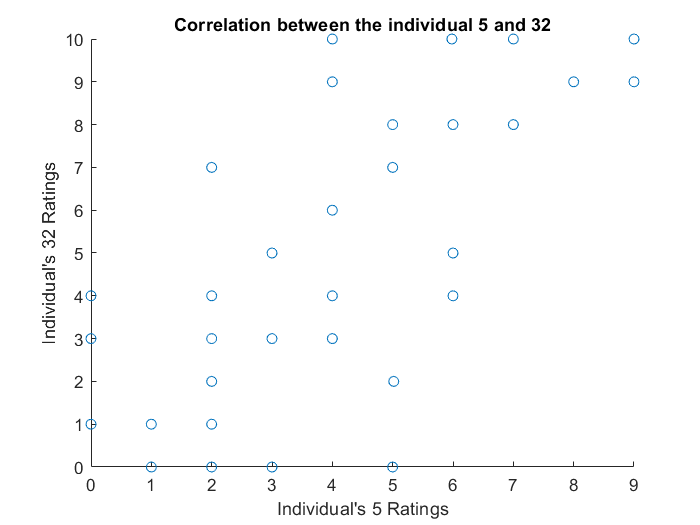


% scatterplot of individuals' 5 and 32 ratings
figure(4)
hold on 
scatter(JTrain(5,:), JTrain(32,:))
xlabel("Individual's 5 Ratings")
ylabel("Individual's 32 Ratings")
title("Correlation between the individual 5 and 32")
hold off

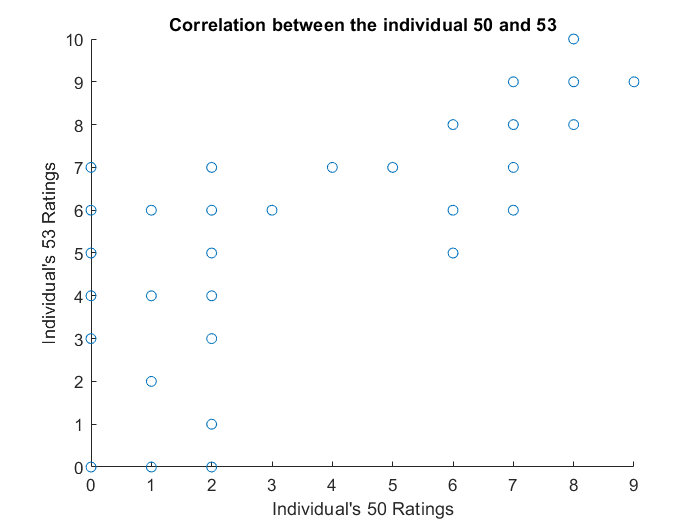

%scatterplot of individuals' 50 and 53 ratings 
figure(5)
hold on
scatter(JTrain(50,:), JTrain(53,:))
xlabel("Individual's 50 Ratings")
ylabel("Individual's 53 Ratings")
title("Correlation between the individual 50 and 53")
hold off

### 3. Clusters 

discussion to insert:

- how did we normalize and reduce the dimensionality of the data

- elbow plot - how did we choose k

- comparison of the 4 clusters

- which clustering does the best job / do the jokes seem to be clustered correctly?

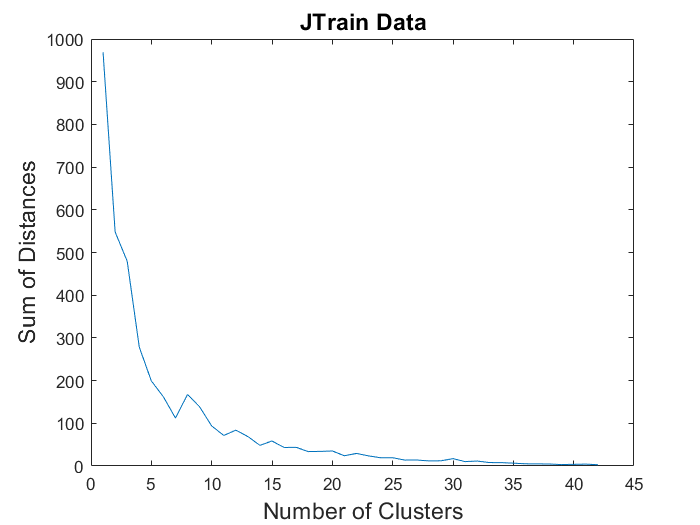


% k means clustering method

% a)Did you reduce the dimensionality of the data set first? If so, how many dimensions did you retain?
% below I am standardizing the data to have a mean of zero and standard deviation of 1
JTrainreduced = normalize(JTrain);
M = 2; % principal number of components to retain
[~,JTrainreduced] = pca(JTrainreduced,'NumComponents',M); 

% b) How many clusters did you end up using? How did you decide on this number?
% use elbow plot to choose k (optimal amount of clusters)

for k = 1:42
    %fprintf("k = %d\n", k); 
    [~,~,sumd] = kmeans(JTrainreduced,k);
    errs(k) = sum(sumd);
end 
%[idx3,C,sumdist3] = kmeans(JTrain,3)

figure(6)
plot(errs)
xlabel("Number of Clusters", 'FontSize',14); 
ylabel("Sum of Distances", 'FontSize',14); 
title("JTrain Data",'FontSize',14); 

 
% optimal k = 9, 15, 17, 25 
% optimal k is observed where there is a bend / elbow in the plot

% c) Do the jokes that were clustered together seem related to you?

figure(7)
f(9) = makekmeansplot(JTrainreduced, 9);

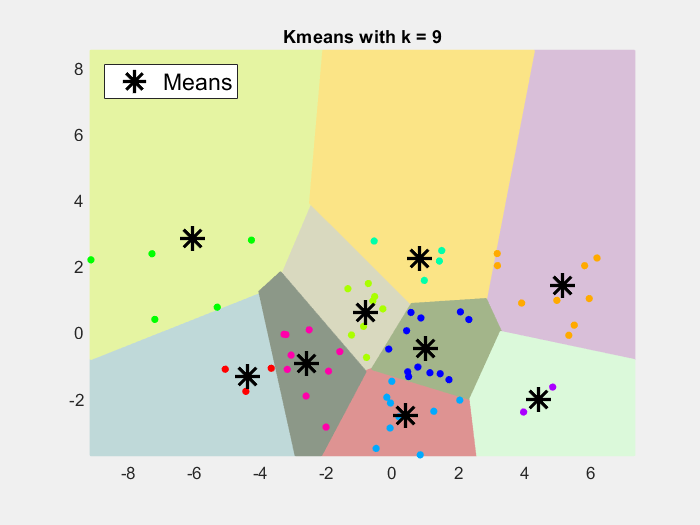

title("Kmeans with k = 9")


figure(8)
f(15) = makekmeansplot(JTrainreduced, 15);

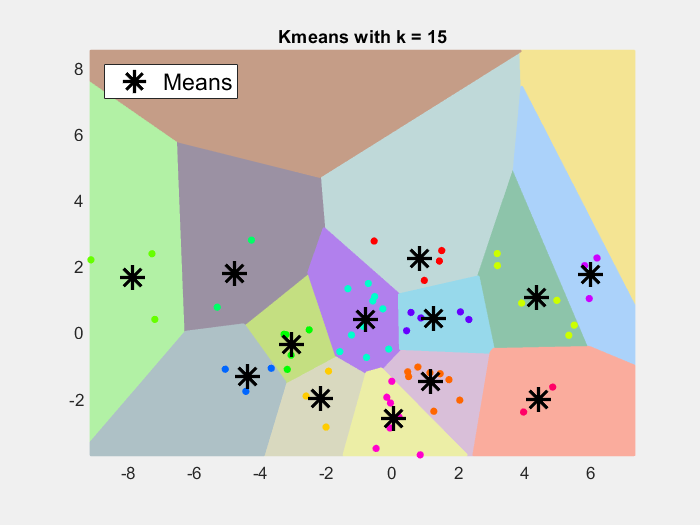

title("Kmeans with k = 15")


figure(9)
f(17) = makekmeansplot(JTrainreduced, 17);

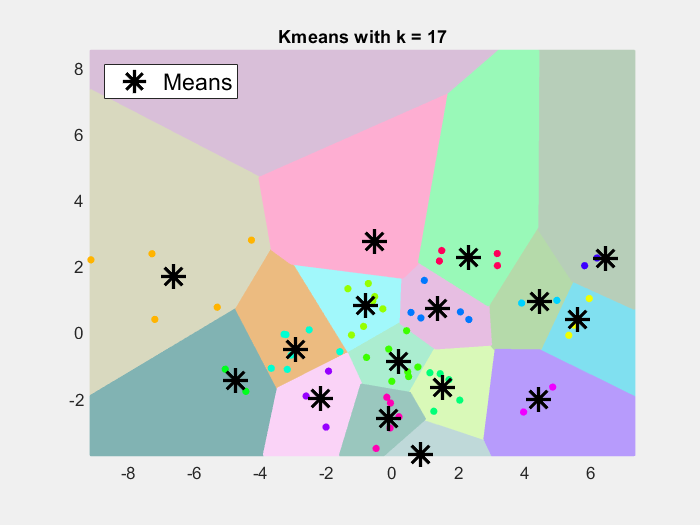

title("Kmeans with k = 17")


figure(10)
f(25) = makekmeansplot(JTrainreduced, 25);

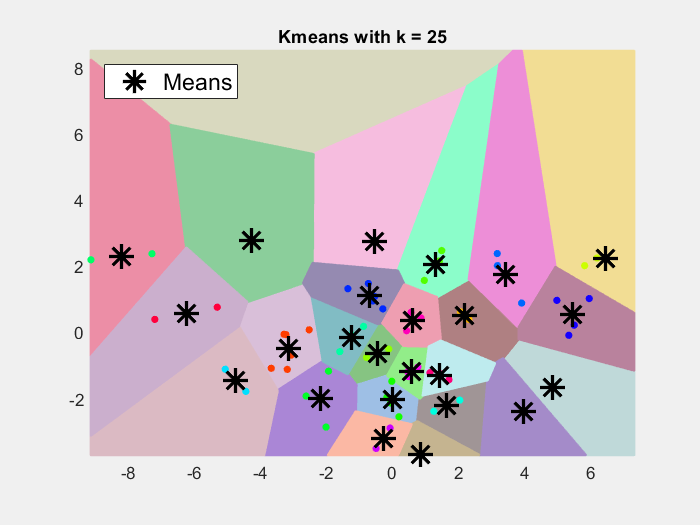

title("Kmeans with k = 25")

### 4. Predictions

discussion to insert:

- we need to try multiple models and discuss how to choose the best one

X = JTrain(1:63, 1:20);
Y = JTrain(1:63, 21:42);
B = X\Y; %20 x 22 - each column gives the parameters for a line of best fit for one of last 22 jokes




predictions = JTest * B;

% calculate error - compare to the average of the the training set for each joke is a 1x22 vector
avglastjokes = mean(Y, 1);
avgpredictions = mean(predictions, 1);
% error between average predictions - measured in frobenius norm
avgerr = norm(avglastjokes - avgpredictions, 'F')

avgerr = 1.5973

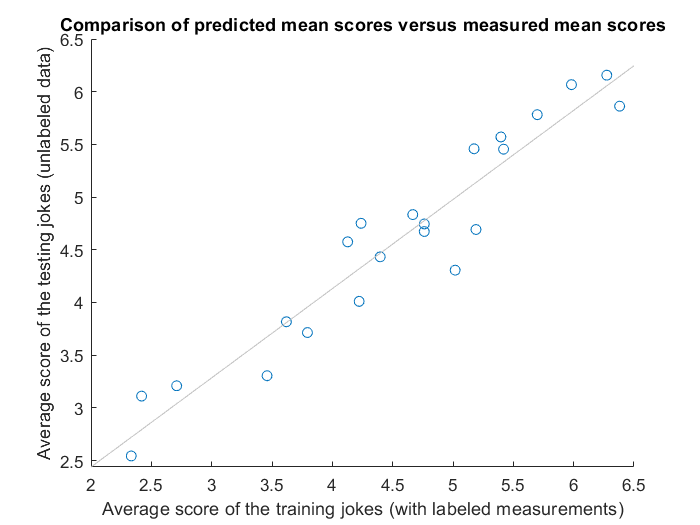


figure(7)
scatter(avglastjokes, avgpredictions)
lsline
xlabel("Average score of the training jokes (with labeled measurements)")
ylabel("Average score of the testing jokes (unlabeled data)")
title("Comparison of predicted mean scores versus measured mean scores")

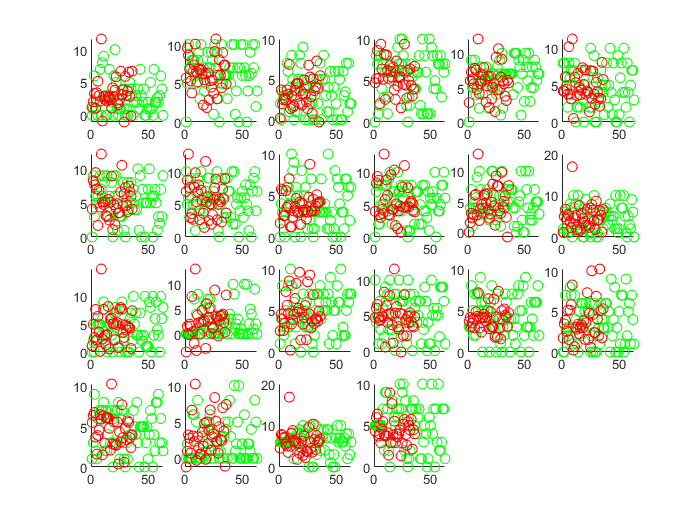


% the plot shows high correlation and frobenius error shows small error values suggesting that the scores were predicted well (in comparison with previous years)




train = JTrain(:, 21:42);
test = predictions;

figure(8)

for i = 1:22
    subplot(4,6,i)
    hold on
    scatter(1:63, train(:, i), 'g')
    scatter(1:36, test(:, i), 'r')
    
    hold off
end 

% note that in th plot above (the red values / predictions) have some
% values greater than 10